# **Concentration Calculation**

**calculatint the concentration of the APT Dataset and visualises the data. The user can plot a bar or a pie chart based on the concentration or counts. **

For the calculation of the concentration, a decomposed pos file and the *colorScheme* is needed .

## Calculates the concentration, count and variance of each ion species

The user can calculate the concentration using the detector efficiency (*detEff*), an *excludeListConc* containing all elements that the user does not want to contribute to the concentration. For example, the user can exclude Ga ions that may be implemented during FIB preparation into the atom probe tip. For example, the detector efficiency of the CAMECA LEAP 4000X HR is 0.37. With *volumeName*, the user has the option to address a specific name to the volume.

detEff = 80; % detector efficiency of the used atom probe, input as a fraction or percentage possible
excludeListConc = {'unranged'}; % list of ions that do not contribute to the concentration calculation 
volumeName = 'Ni_OLO_Ox_769_0611b'; % name of the volume
conc = posCalculateConcentrationSimple(posRaw,detEff,excludeListConc,volumeName); % calculates the count, concentration, and variance
 

## Plots the concentration or count as a bar or pie chart 

The user can plot the concentration or count as a bar or pie chart. Again, a exlude list (*exludeListChart*) can be specified in order to determine which ion's concentration should be displayed. Furthermore, the user can choose between linear and logarithmic scale for the y axis. For pie chart only linear (*lin*) is advisable.

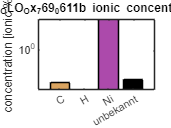

format = 'concentration';
excludeListChart = {'unranged'}; % list of ions which should not be visualised
plotType = 'bar'; % specification of plot type
[p, ax, f] = concentrationPlot(conc([conc.format==format],:),excludeListChart,plotType,colorScheme);
ax.YScale = 'log'; % log scale is only advisable for bar chart as the plot type